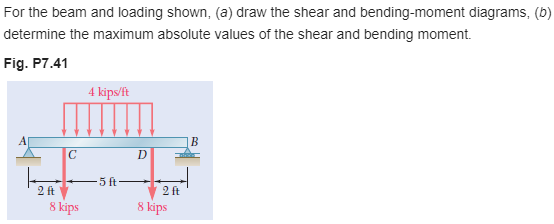

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 9*u.ft);
b = b.add('concentrated', 'force', -8*u.kip, 2*u.ft);
b = b.add('concentrated', 'force', -8*u.kip, 7*u.ft);
b = b.add('distributed', 'force', -4*u.kip/u.ft, [2 7]*u.ft);
b.L = 9*u.ft;

# elastic curve

[y dy m v w rs ra] = b.elastic_curve('factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(881\,{\mathrm{ft}}^{2}-18\,x^{2}\right)}{6\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\leq 2\,\mathrm{ft}\\ \frac{-x^{4}+18\,x^{3}\,\mathrm{ft}+24\,x^{2}\,{\mathrm{ft}}^{2}-945\,x\,{\mathrm{ft}}^{3}+48\,{\mathrm{ft}}^{4}}{6\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\in \left(2\,\mathrm{ft},7\,\mathrm{ft}\right]\\ -\frac{\left(x-9\,\mathrm{ft}\right)\,\left(18\,x^{2}-324\,x\,\mathrm{ft}+577\,{\mathrm{ft}}^{2}\right)}{6\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }7\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{881\,{\mathrm{ft}}^{2}-54\,x^{2}}{6\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\leq 2\,\mathrm{ft}\\ \frac{\left(2\,x-9\,\mathrm{ft}\right)\,\left(-2\,x^{2}+18\,x\,\mathrm{ft}+105\,{\mathrm{ft}}^{2}\right)}{6\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\in \left(2\,\mathrm{ft},7\,\mathrm{ft}\right]\\ -\frac{54\,x^{2}-972\,x\,\mathrm{ft}+3493\,{\mathrm{ft}}^{2}}{6\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }7\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} 18\,x\,\mathrm{kip} & \text{ if }x\leq 2\,\mathrm{ft}\\ 2\,\left(-x^{2}+9\,x\,\mathrm{ft}+4\,{\mathrm{ft}}^{2}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\in \left(2\,\mathrm{ft},7\,\mathrm{ft}\right]\\ -18\,\left(x-9\,\mathrm{ft}\right)\,\mathrm{kip} & \text{ if }7\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 18\,\mathrm{kip} & \text{ if }x\leq 2\,\mathrm{ft}\\ -2\,\left(2\,x-9\,\mathrm{ft}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\in \left(2\,\mathrm{ft},7\,\mathrm{ft}\right]\\ -18\,\mathrm{kip} & \text{ if }7\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<2\,\mathrm{ft}\\ -4\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\in \left[2\,\mathrm{ft},7\,\mathrm{ft}\right]\\ 0 & \text{ if }7\,\mathrm{ft}<x \end{array}\right.$$

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 18\,\mathrm{kip}\\ \mathrm{Rb} & 18\,\mathrm{kip} \end{array}\right)$$

# shear and moment diagram

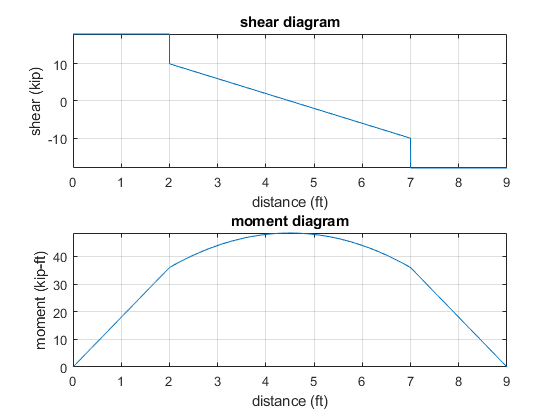

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# absolute maximum shear and bending moment

V_max = v(0)

$$V\_max = 18\,\mathrm{kip}$$

M_max = m(b.L/2);
M_max_vpa = vpa(M_max) %#ok

$$M\_max\_vpa = 48.5\,\mathrm{ft}\,\mathrm{kip}$$

# clean up

addvar(y);
setassum(old_assum, 'clear');
clear M_max_vpa old_assum;